# Práctica 3B. SVD aplicado a compresión de imágenes

Nombre del alumno (DNI)

### 1. Cargado de imágenes

1a. Descargar la imagen `lena512.bmp` de Moodle

1b. Cargar la imagen con el comando `imread`. 

El formato de datos es `uint8`, es preferible convertirlo a `double`.

A=imread('lena512.bmp')

A = 512×512 uint8 matrix
   162   162   162   161   162   157   163   161   166   162   162   160   155   163   160   155   157   156   161   161   154   156   154   157   153   157   154   152   156   154   154   156   154   158   155   160   158   167   160   166   166   165   166   172   171   175   173   170   172   172
   162   162   162   161   162   157   163   161   166   162   162   160   155   163   160   155   157   156   161   161   154   156   154   157   153   157   154   152   156   154   154   156   154   158   155   160   158   167   160   166   166   165   166   172   171   175   173   170   172   172
   162   162   162   161   162   157   163   161   166   162   162   160   155   163   160   155   157   156   161   161   154   156   154   157   153   157   154   152   156   154   154   156   154   158   155   160   158   167   160   166   166   165   166   172   171   175   173   170   172   172
   162   162   162   161   162   157   163   161   166   162   162   160

A2=im2double(A,'indexed')

A2 =    163   163   163   162   163   158   164   162   167   163   163   161   156   164   161   156   158   157   162   162   155   157   155   158   154   158   155   153   157   155   155   157   155   159   156   161   159   168   161   167   167   166   167   173   172   176   174   171   173   173
   163   163   163   162   163   158   164   162   167   163   163   161   156   164   161   156   158   157   162   162   155   157   155   158   154   158   155   153   157   155   155   157   155   159   156   161   159   168   161   167   167   166   167   173   172   176   174   171   173   173
   163   163   163   162   163   158   164   162   167   163   163   161   156   164   161   156   158   157   162   162   155   157   155   158   154   158   155   153   157   155   155   157   155   159   156   161   159   168   161   167   167   166   167   173   172   176   174   171   173   173
   163   163   163   162   163   158   164   162   167   163   163   161   156   164   161  

1c. Mostramos la imagen, cambiando a escala de grises. Configurar en escala de grises con el comando `colormap(gray(256)) `y representar la imagen con el comando `image`.

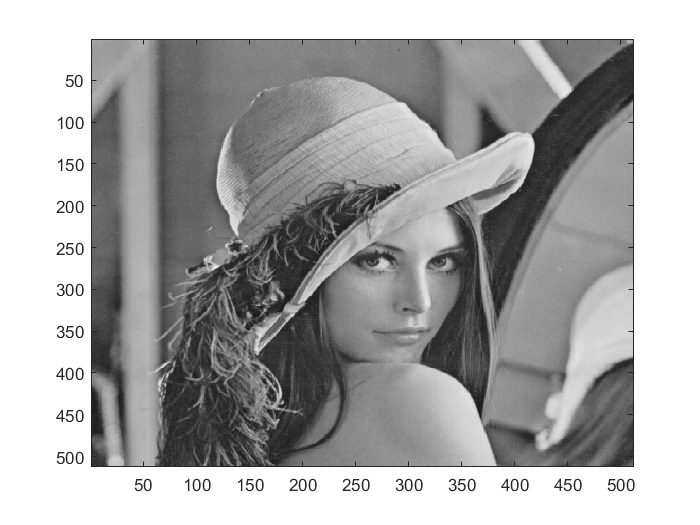

colormap(gray(256));
image(A2)

### 2. Descomposición SVD 

2a. Utilizar el comando `svd` de MATLAB calcular la factorización de lena.

[U,S,v]=svd(A2)

U =    -0.0473    0.0279   -0.0152    0.0330    0.0401    0.0342    0.0150    0.0316    0.0100   -0.0133    0.0278    0.0019    0.0908   -0.0419    0.0575    0.0226    0.0194   -0.0139    0.0079   -0.0292    0.0226   -0.0589   -0.0235   -0.0447    0.0247    0.0331   -0.0440   -0.0148    0.0473    0.0139   -0.0618    0.0262   -0.0224   -0.0065    0.0188    0.0648    0.0536    0.0253   -0.0096    0.0454   -0.0648   -0.0429   -0.0019   -0.0387   -0.0395    0.0119    0.0203   -0.0120   -0.0190    0.0096
   -0.0473    0.0279   -0.0152    0.0330    0.0401    0.0342    0.0150    0.0316    0.0100   -0.0133    0.0278    0.0019    0.0908   -0.0419    0.0575    0.0226    0.0194   -0.0139    0.0079   -0.0292    0.0226   -0.0589   -0.0235   -0.0447    0.0247    0.0331   -0.0440   -0.0148    0.0473    0.0139   -0.0618    0.0262   -0.0224   -0.0065    0.0188    0.0648    0.0536    0.0253   -0.0096    0.0454   -0.0648   -0.0429   -0.0019   -0.0387   -0.0395    0.0119    0.0203   -0.0120   -0.0190    0

S = 	1.0e+04 *

    6.5239         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0596         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

v =    -0.0334    0.0267   -0.0194    0.0446   -0.0152    0.1068   -0.0394    0.0374   -0.0608   -0.0438    0.0103   -0.0008    0.0037   -0.0216    0.0298   -0.0403    0.0041   -0.0000   -0.0122    0.0586   -0.0555    0.0036   -0.0019   -0.0205   -0.0254    0.0253   -0.0020    0.0319   -0.0109    0.0045   -0.0189    0.0104   -0.0465    0.0176   -0.0017    0.0338   -0.0065    0.0215   -0.0059    0.0344   -0.0569    0.0230    0.0071   -0.0207   -0.0084    0.0172    0.0092   -0.0630   -0.0406    0.0359
   -0.0334    0.0268   -0.0194    0.0445   -0.0153    0.1068   -0.0394    0.0375   -0.0608   -0.0438    0.0103   -0.0009    0.0035   -0.0215    0.0299   -0.0408    0.0041   -0.0001   -0.0124    0.0586   -0.0553    0.0033   -0.0019   -0.0209   -0.0250    0.0257   -0.0024    0.0315   -0.0107    0.0048   -0.0185    0.0105   -0.0466    0.0173   -0.0021    0.0342   -0.0057    0.0214   -0.0055    0.0342   -0.0571    0.0226    0.0072   -0.0206   -0.0080    0.0168    0.0089   -0.0627   -0.0408    0

2b. Comprobar que la factorización está bien hecha:

norm(A2-(U*S*v'))

ans = 3.0068e-10

2c. Estudio de los valores principales:

Representar los valores singulares en escala pseudo-logaritmica usando el comando `semilogy`

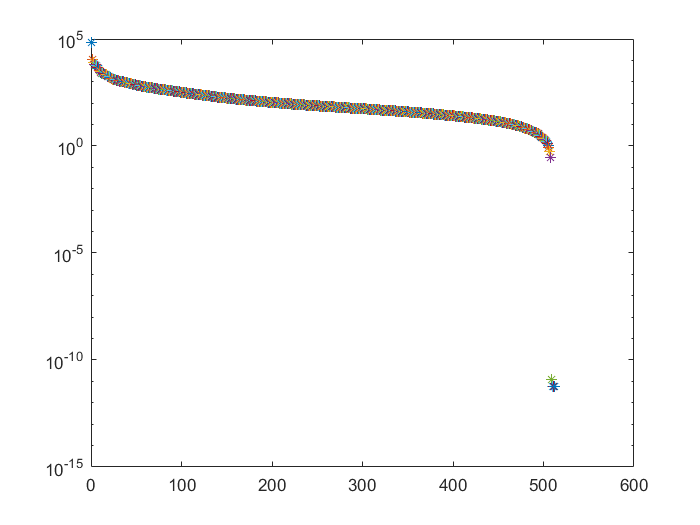

[n,]
semilogy(S,'*')

### 3. Compresión de la imagen

3a. Calculamos las imágenes comprimidas (proyecciones) sobre los k primeros valores principales. 

Calcular `k=256,128,64,32 y 16`

3b. Representar esta imágenes comprimidas, y compararlas